%Generate Required Data Vectors
%robot state (Position)
x_result = result.x(find(names == 'x0'):find(names == x_label(end)));
y_result = result.x(find(names == 'y0'):find(names == y_label(end)));
theta_result = result.x(find(names == 'theta0'):find(names == theta_label(end)));

%robot state (Velocity)
xdot_result = result.x(find(names == 'xdot0'):find(names == xdot_label(end)));
ydot_result = result.x(find(names == 'ydot0'):find(names == ydot_label(end)));
thetadot_result = result.x(find(names == 'thetadot0'):find(names == thetadot_label(end)));

%Contact Configuration
CF_result = result.x(find(names == 'CF0'):find(names == CF_label(end)));
CH_result = result.x(find(names == 'CH0'):find(names == CH_label(end)));

%end-effector locations
PFx_result = result.x(find(names == 'PFx0'):find(names == PFx_label(end)));
PFy_result = result.x(find(names == 'PFy0'):find(names == PFy_label(end)));
PHx_result = result.x(find(names == 'PHx0'):find(names == PHx_label(end)));
PHy_result = result.x(find(names == 'PHy0'):find(names == PHy_label(end)));

%end-effector velocities
PFxdot_result = result.x(find(names == 'PFxdot0'):find(names == PFxdot_label(end)));
PFydot_result = result.x(find(names == 'PFydot0'):find(names == PFydot_label(end)));
PHxdot_result = result.x(find(names == 'PHxdot0'):find(names == PHxdot_label(end)));
PHydot_result = result.x(find(names == 'PHydot0'):find(names == PHydot_label(end))); 

%contact force result
FFx_result = result.x(find(names == 'FFx0'):find(names == FFx_label(end)));
FFy_result = result.x(find(names == 'FFy0'):find(names == FFy_label(end)));
FHx_result = result.x(find(names == 'FHx0'):find(names == FHx_label(end)));
FHy_result = result.x(find(names == 'FHy0'):find(names == FHy_label(end)));

NetForceX = FFx_result + FHx_result;
NetForceY = FFy_result + FHy_result;

%Torque on the body
FrontTorque_result = (PFx_result - x_result).*FFy_result - (PFy_result - y_result).*FFx_result;
HindTorque_result = (PHx_result - x_result).*FHy_result - (PHy_result - y_result).*FHx_result;

NetTorque = FrontTorque_result + HindTorque_result;

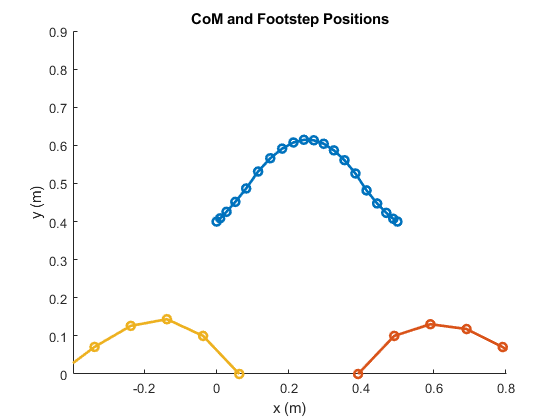

%Plot Optimization Result
figNum = 1;

%Plot CoM and FootStep Locations
figure(figNum)
hold on
plot(x_result, y_result, '-o', 'LineWidth', 2)
plot(PFx_result, PFy_result, '-o', 'LineWidth', 2)
plot(PHx_result, PHy_result, '-o', 'LineWidth', 2)
title('CoM and Footstep Positions')
xlabel('x (m)')
ylabel('y (m)')
hold off

xlim([-0.397 0.803])
ylim([0.000 0.900])

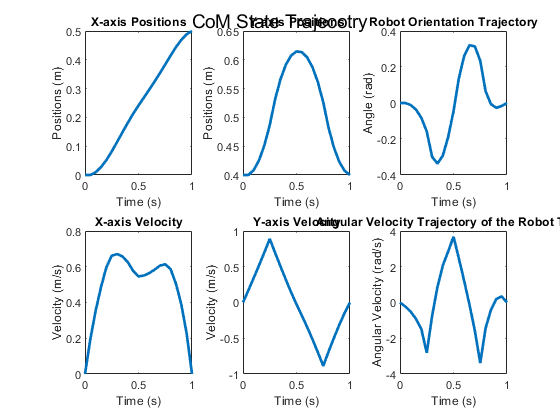


figNum = figNum + 1;

%Plot CoM States
figure(figNum)
suptitle('CoM State Trajecotry')

subplot(2,3,1)
plot(TimeSeries, x_result, 'LineWidth', 2)
title('X-axis Positions')
xlabel('Time (s)')
ylabel('Positions (m)')

subplot(2,3,2)
plot(TimeSeries, y_result, 'LineWidth', 2)
title('Y-axis Positions')
xlabel('Time (s)')
ylabel('Positions (m)')

subplot(2,3,3)
plot(TimeSeries, theta_result, 'LineWidth', 2)
title('Robot Orientation Trajectory')
xlabel('Time (s)')
ylabel('Angle (rad)')

subplot(2,3,4)
plot(TimeSeries, xdot_result, 'LineWidth', 2)
title('X-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')

subplot(2,3,5)
plot(TimeSeries, ydot_result, 'LineWidth', 2)
title('Y-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')

subplot(2,3,6)
plot(TimeSeries, thetadot_result, 'LineWidth', 2)
title('Angular Velocity Trajectory of the Robot Torso')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')

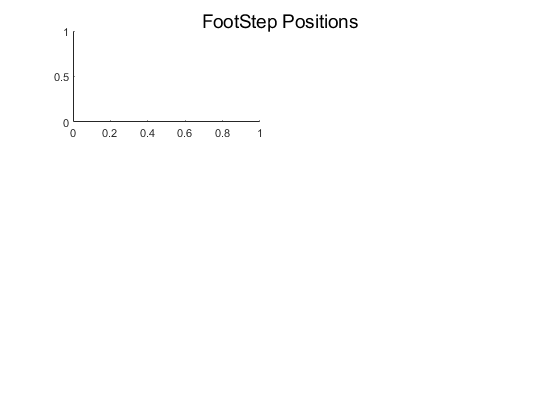


figNum = figNum + 1;

%Plot Footstep Positions 
figure(figNum)
suptitle('FootStep Positions')

subplot(3,2,1)

stairs(TimeSeries, CF_result, 'LineWidth', 2)

Error using stairs (line 53)
The length of X must match the number of rows of Y.

title('Front Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuation')

subplot(3,2,2)
stairs(TimeSeries, CH_result, 'LineWidth', 2)
title('Hind Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')

subplot(3,2,3)
stairs(TimeSeries, PFx_result, 'LineWidth', 2)
title('X-axis Position of Front Leg')
xlabel('Time(s)')
ylabel('Position (m)')

subplot(3,2,4)
stairs(TimeSeries, PHx_result, 'LineWidth', 2)
title('X-axis Position of Hind Leg')
xlabel('Time (s)')
ylabel('Position (m)')

subplot(3,2,5)
stairs(TimeSeries, PFy_result, 'LineWidth', 2)
title('Y-axis Position of Front Leg')
xlabel('Time (s)')
ylabel('Position (m)')

subplot(3,2,6)
stairs(TimeSeries, PHy_result, 'LineWidth', 2)
title('Y-axis Position of Hind Leg')
xlabel('Time (s)')
ylabel('Position (m)')

figNum = figNum + 1;

%Plot Foot Velocity
figure(figNum)
suptitle('Foot Swing Velocity')

subplot(3,2,1)
stairs(TimeSeries, CF_result, 'LineWidth', 2)
title('Front Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')

subplot(3,2,2)
stairs(TimeSeries, CH_result, 'LineWidth',2)
title('Hind Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')

subplot(3,2,3)
stairs(TimeSeries, PFxdot_result, 'LineWidth', 2)
title('Front Leg X-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')

subplot(3,2,4)
stairs(TimeSeries, PHxdot_result, 'LineWidth', 2)
title('Hind Leg X-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')

subplot(3,2,5)
stairs(TimeSeries, PFydot_result, 'LineWidth', 2)
title('Front Leg Y-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')

subplot(3,2,6)
stairs(TimeSeries, PHydot_result, 'LineWidth', 2)
title('Hind Leg Y-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')

figNum = figNum + 1;

%Plot Foot-Ground Reaction Forces
figure(figNum)
suptitle('Foot-Ground Reaction Forces')

subplot(3,2,1)
stairs(TimeSeries, CF_result, 'LineWidth', 2)
title('Front Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')

subplot(3,2,2)
stairs(TimeSeries, CH_result, 'LineWidth', 2)
title('Hind Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')

subplot(3,2,3)
stairs(TimeSeries, FFx_result, 'LineWidth', 2)
title('Front Leg Force X-axis')
xlabel('Time (s)')
ylabel('Foot-Ground Reaction Forces (N)')

subplot(3,2,4)
stairs(TimeSeries, FHx_result, 'LineWidth', 2)
title('Hind Leg Force X-axis')
xlabel('Time (s)')
ylabel('Foot-Ground Reaction Forces (N)')

subplot(3,2,5)
stairs(TimeSeries, FFy_result, 'LineWidth', 2)
title('Front Leg Force Y-axis')
xlabel('Time (s)')
ylabel('Foot-Grond Reaction Forces (N)')

subplot(3,2,6)
stairs(TimeSeries, FHy_result, 'LineWidth', 2)
title('Hind Leg Force Y-axis')
xlabel('Time (s)')
ylabel('Foot-Ground Reaction Forces (N)')

figNum = figNum + 1;

%Plot Torque exerted on robot torso
figure(figNum)
suptitle('Torques Generated by Each Leg')

subplot(2,2,1)
stairs(TimeSeries, CF_result, 'LineWidth', 2)
title('Front Leg Foot-Ground Contact Configurations 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configurations')

subplot(2,2,2)
stairs(TimeSeries, CH_result, 'LineWidth', 2)
title('Hind Leg Foot-Ground COntact Configurations 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')

subplot(2,2,3)
stairs(TimeSeries, FrontTorque_result, 'LineWidth', 2)
title('Front Leg Torque')
xlabel('Time (s)')
ylabel('Torque (Nm)')

subplot(2,2,4)
stairs(TimeSeries, HindTorque_result, 'LineWidth', 2)
title('Hind Leg Torque')
xlabel('TIme(s)')
ylabel('Torque (Nm)')

figNum = figNum + 1;


%Plot Net Forces and Torques exerted on the robot torso
figure(figNum)
suptitle('Net Forces and Torques on the Robot Torso')

subplot(3,1,1)
stairs(TimeSeries, NetForceX, 'LineWidth', 2)
title('X-axis Net Force')
xlabel('Time (s)')
ylabel('Force (N)')

subplot(3,1,2)
stairs(TimeSeries, NetForceY, 'LineWidth', 2)
title('Y-axis Net Force')
xlabel('Time (s)')
ylabel('Force (N)')

subplot(3,1,3)
stairs(TimeSeries, NetTorque, 'LineWidth', 2)
title('Net Torque')
xlabel('Time(s)')
ylabel('Torque (Nm)')

figNum = figNum + 1;

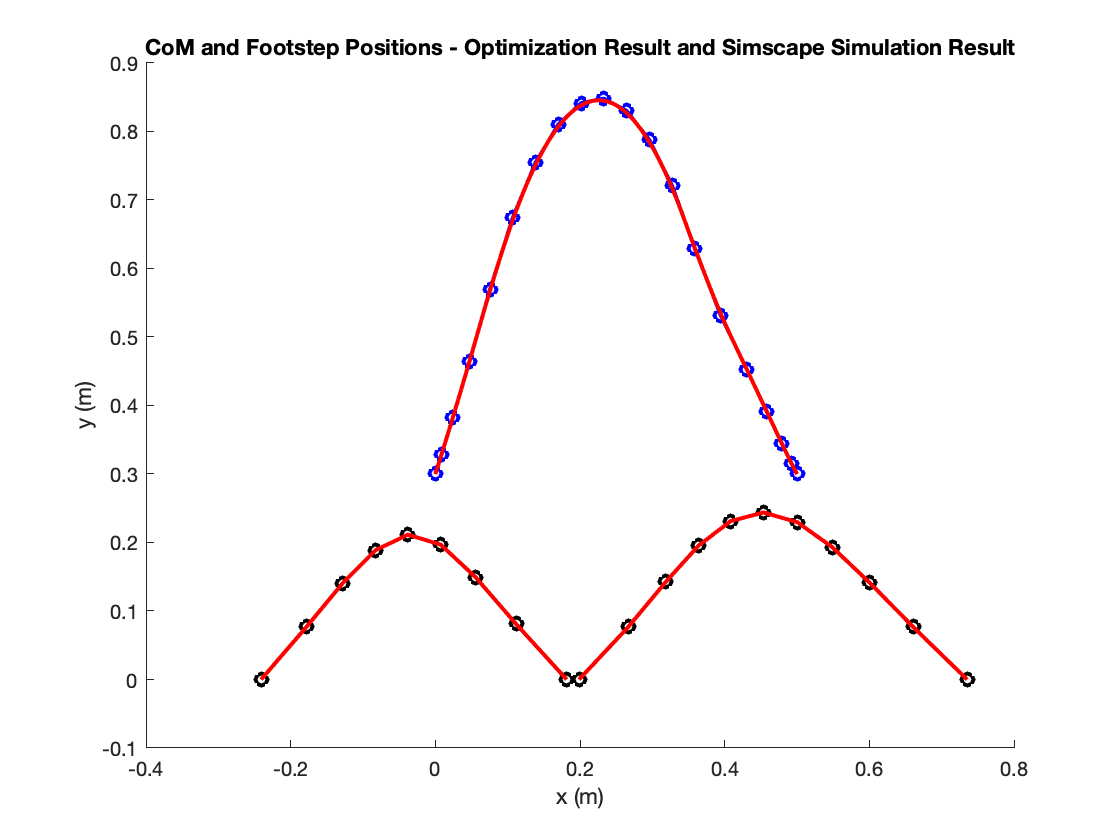

%Plot Optimization Result with Simulink Simulation Result
figNum = 1;

%Plot CoM Position and Foot Trajectory
figure(figNum)
figNum = figNum + 1;

hold on
plot(x_result, y_result, 'b-o', 'LineWidth', 2)
plot(PFx_result, PFy_result, 'k-o', 'LineWidth', 2)
plot(PHx_result, PHy_result, 'k-o', 'LineWidth', 2)
plot(x_simout.signals.values, y_simout.signals.values, 'r', 'LineWidth', 2)
plot(PFx_simout.signals.values, PFy_simout.signals.values, 'r', 'LineWidth', 2)
plot(PHx_simout.signals.values, PHy_simout.signals.values, 'r', 'LineWidth', 2)
title('CoM and Footstep Positions - Optimization Result and Simscape Simulation Result')
xlabel('x (m)')
ylabel('y (m)')
hold off

Red Curve: Simulation Result from SimScape

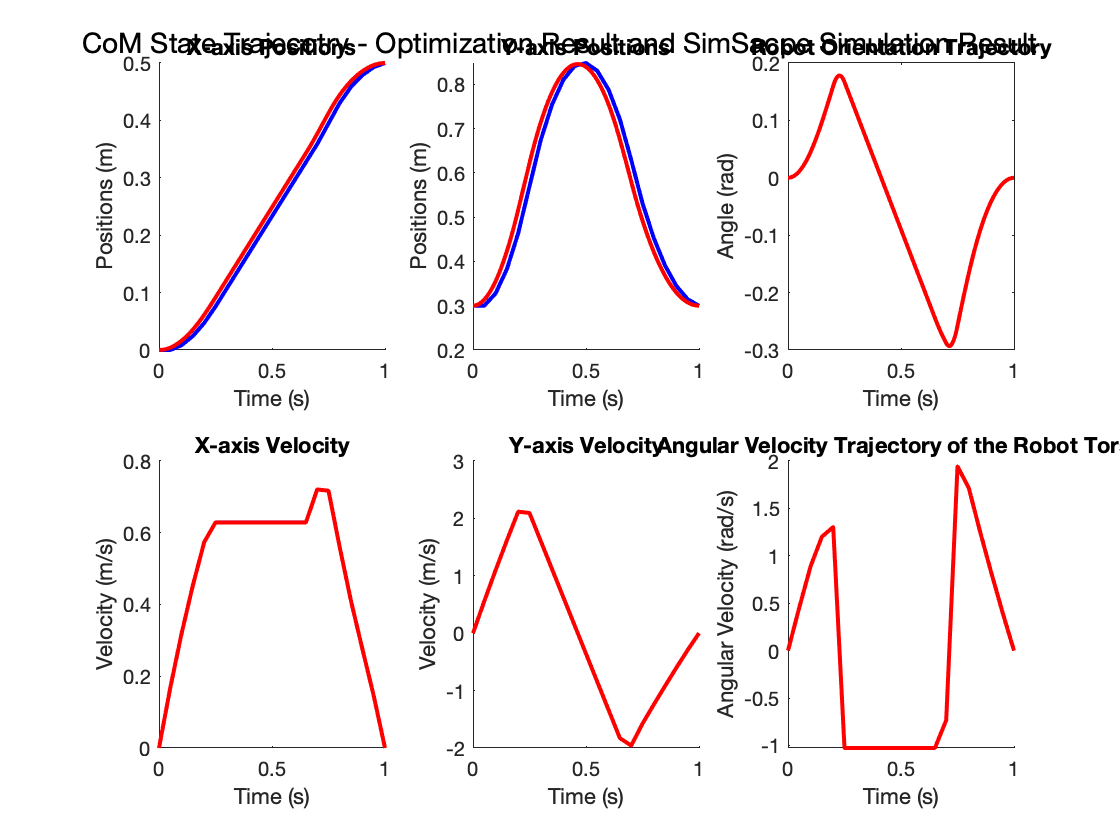

%Plot CoM States
figure(figNum)
figNum = figNum + 1;

suptitle('CoM State Trajecotry - Optimization Result and SimSacpe Simulation Result')

subplot(2,3,1)
hold on
plot(TimeSeries, x_result, 'b', 'LineWidth', 2)
plot(x_simout.time, x_simout.signals.values, 'r', 'LineWidth', 2)
title('X-axis Positions')
xlabel('Time (s)')
ylabel('Positions (m)')
hold off

subplot(2,3,2)
hold on
plot(TimeSeries, y_result, 'b', 'LineWidth', 2)
plot(y_simout.time, y_simout.signals.values, 'r', 'LineWidth', 2)
title('Y-axis Positions')
xlabel('Time (s)')
ylabel('Positions (m)')
hold off

subplot(2,3,3)
plot(TimeSeries, theta_result, 'b', 'LineWidth', 2)
plot(theta_simout.time, theta_simout.signals.values, 'r', 'LineWidth', 2)
title('Robot Orientation Trajectory')
xlabel('Time (s)')
ylabel('Angle (rad)')

subplot(2,3,4)
hold on
plot(TimeSeries, xdot_result, 'b', 'LineWidth', 2)
plot(xdot_simout.time, xdot_simout.signals.values, 'r', 'LineWidth', 2)
title('X-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold off

subplot(2,3,5)
hold on
plot(TimeSeries, ydot_result, 'b', 'LineWidth', 2)
plot(ydot_simout.time, ydot_simout.signals.values, 'r', 'LineWidth', 2)
title('Y-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold off

subplot(2,3,6)
hold on
plot(TimeSeries, thetadot_result, 'b', 'LineWidth', 2)
plot(thetadot_simout.time, thetadot_simout.signals.values, 'r', 'LineWidth', 2)
title('Angular Velocity Trajectory of the Robot Torso')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
hold off

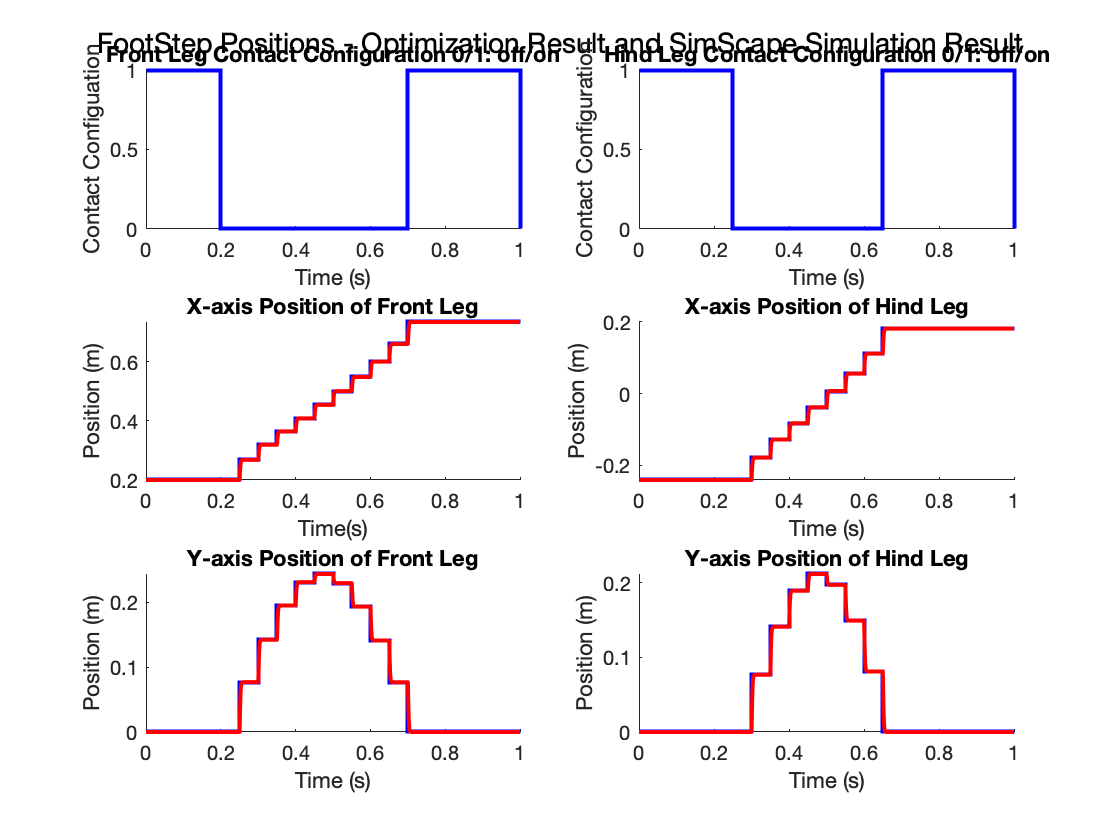

%Plot Footstep Positions 
figure(figNum)
figNum = figNum + 1;

suptitle('FootStep Positions - Optimization Result and SimScape Simulation Result')

subplot(3,2,1)
hold on
stairs(TimeSeries, CF_result, 'b','LineWidth', 2)
title('Front Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuation')
hold off

subplot(3,2,2)
hold on
stairs(TimeSeries, CH_result, 'b', 'LineWidth', 2)
title('Hind Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')
hold off

subplot(3,2,3)
hold on
stairs(TimeSeries, PFx_result, 'b', 'LineWidth', 2)
plot(PFx_simout.time, PFx_simout.signals.values, 'r', 'LineWidth', 2)
title('X-axis Position of Front Leg')
xlabel('Time(s)')
ylabel('Position (m)')
hold off

subplot(3,2,4)
hold on
stairs(TimeSeries, PHx_result, 'b', 'LineWidth', 2)
plot(PHx_simout.time, PHx_simout.signals.values, 'r', 'LineWidth', 2)
title('X-axis Position of Hind Leg')
xlabel('Time (s)')
ylabel('Position (m)')
hold off

subplot(3,2,5)
hold on
stairs(TimeSeries, PFy_result, 'b', 'LineWidth', 2)
plot(PFy_simout.time, PFy_simout.signals.values, 'r', 'LineWidth', 2)
title('Y-axis Position of Front Leg')
xlabel('Time (s)')
ylabel('Position (m)')
hold off

subplot(3,2,6)
hold on
stairs(TimeSeries, PHy_result, 'b', 'LineWidth', 2)
plot(PHy_simout.time, PHy_simout.signals.values, 'r', 'LineWidth', 2)
title('Y-axis Position of Hind Leg')
xlabel('Time (s)')
ylabel('Position (m)')
hold off

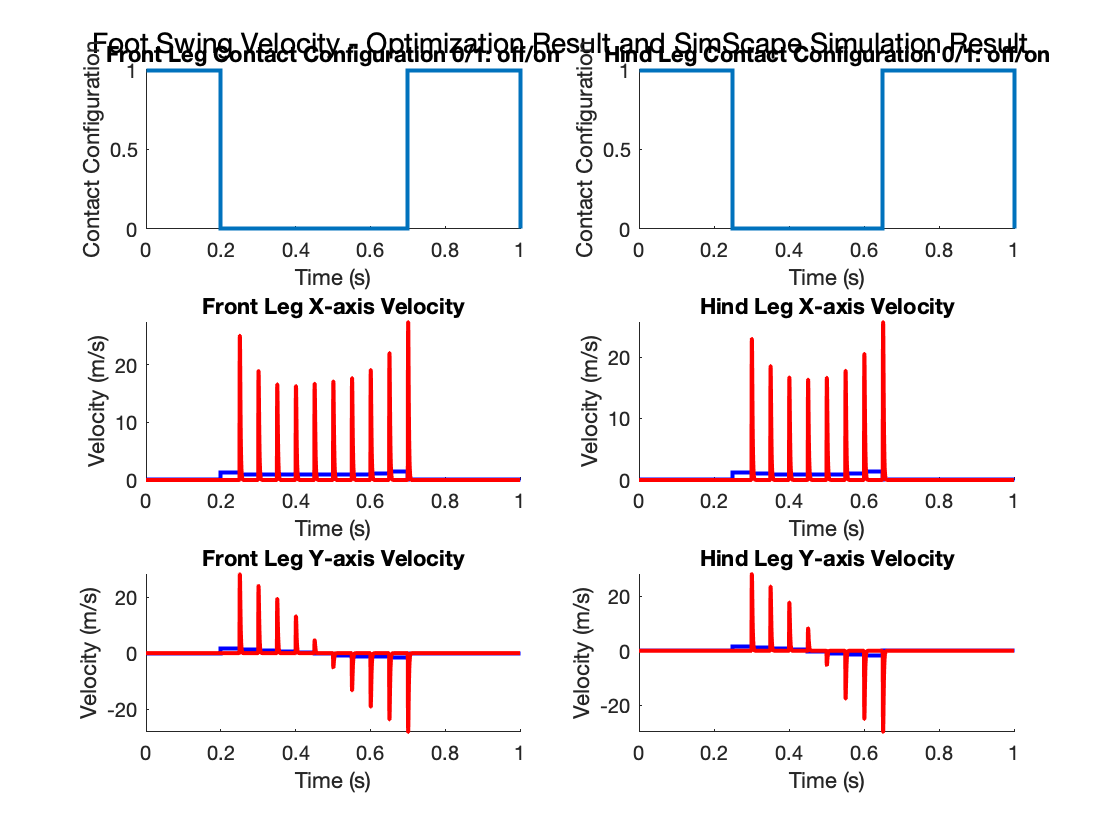

%Plot Foot Velocity
figure(figNum)
figNum = figNum + 1;

suptitle('Foot Swing Velocity - Optimization Result and SimScape Simulation Result')

subplot(3,2,1)
hold on
stairs(TimeSeries, CF_result, 'LineWidth', 2)
title('Front Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')
hold off

subplot(3,2,2)
hold on
stairs(TimeSeries, CH_result, 'LineWidth',2)
title('Hind Leg Contact Configuration 0/1: off/on')
xlabel('Time (s)')
ylabel('Contact Configuration')
hold off

subplot(3,2,3)
hold on
stairs(TimeSeries, PFxdot_result, 'b', 'LineWidth', 2)
plot(PFxdot_simout.time, PFxdot_simout.signals.values, 'r', 'LineWidth', 2)
title('Front Leg X-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold off

subplot(3,2,4)
hold on
stairs(TimeSeries, PHxdot_result, 'b', 'LineWidth', 2)
plot(PHxdot_simout.time, PHxdot_simout.signals.values, 'r', 'LineWidth', 2)
title('Hind Leg X-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold off

subplot(3,2,5)
hold on
stairs(TimeSeries, PFydot_result, 'b', 'LineWidth', 2)
plot(PFydot_simout.time, PFydot_simout.signals.values, 'r', 'LineWidth', 2)
title('Front Leg Y-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold off

subplot(3,2,6)
hold on
stairs(TimeSeries, PHydot_result, 'b', 'LineWidth', 2)
plot(PHydot_simout.time, PHydot_simout.signals.values, 'r', 'LineWidth', 2)
title('Hind Leg Y-axis Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold off

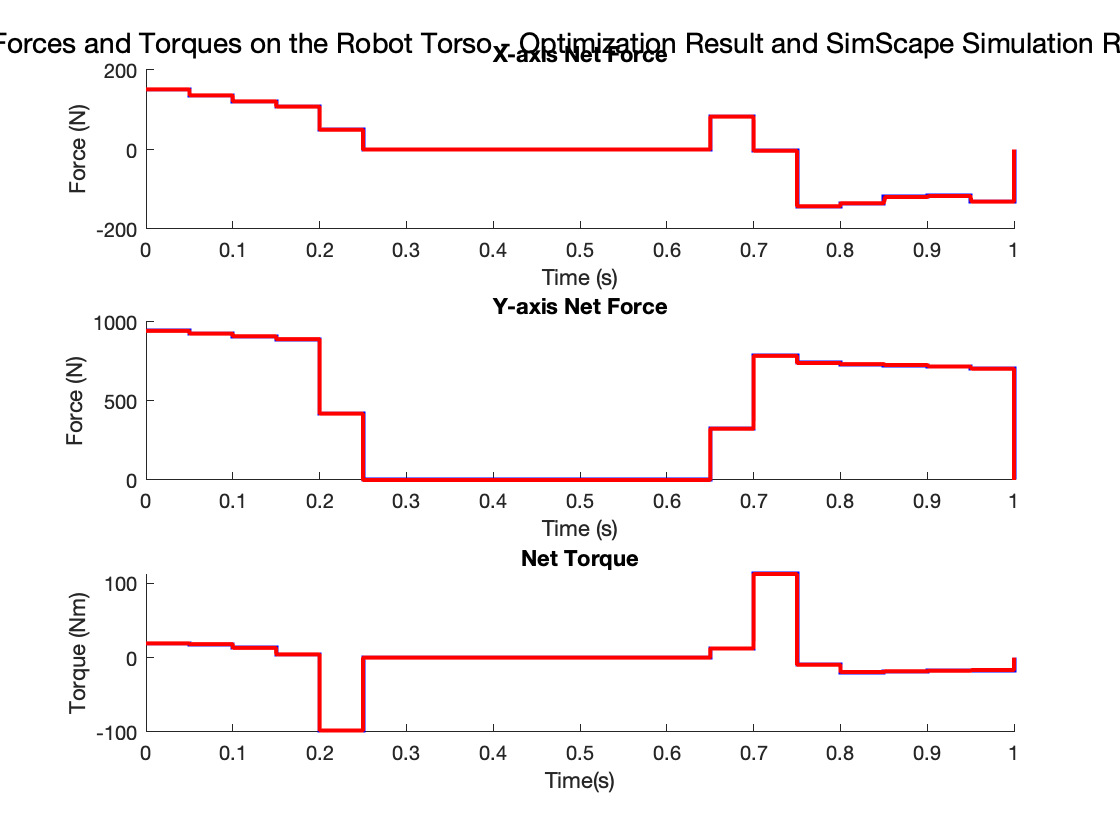

%Plot Net Forces and Torques exerted on the robot torso
figure(figNum)
figNum = figNum + 1;

suptitle('Net Forces and Torques on the Robot Torso - Optimization Result and SimScape Simulation Result')

subplot(3,1,1)
hold on
stairs(TimeSeries, NetForceX, 'b', 'LineWidth', 2)
plot(NetForceX_simout.time, NetForceX_simout.signals.values, 'r', 'LineWidth', 2)
title('X-axis Net Force')
xlabel('Time (s)')
ylabel('Force (N)')
hold off

subplot(3,1,2)
hold on
stairs(TimeSeries, NetForceY, 'b', 'LineWidth', 2)
plot(NetForceY_simout.time, NetForceY_simout.signals.values, 'r', 'LineWidth', 2)
title('Y-axis Net Force')
xlabel('Time (s)')
ylabel('Force (N)')
hold off

subplot(3,1,3)
hold on
stairs(TimeSeries, NetTorque, 'b', 'LineWidth', 2)
plot(NetTorque_simout.time, NetTorque_simout.signals.values, 'r', 'LineWidth', 2)
title('Net Torque')
xlabel('Time(s)')
ylabel('Torque (Nm)')
hold off